# Melanoma or Not?

This example uses transfer learning to train a deep network that can classify images of roundworms as either alive or dead. (Alive worms are round; dead ones are straight.)

## Get the training images and classes

Create a datastore to the images.

imds = imageDatastore("SkinImages",LabelSource="foldernames",IncludeSubfolders=true);

View the first few images.

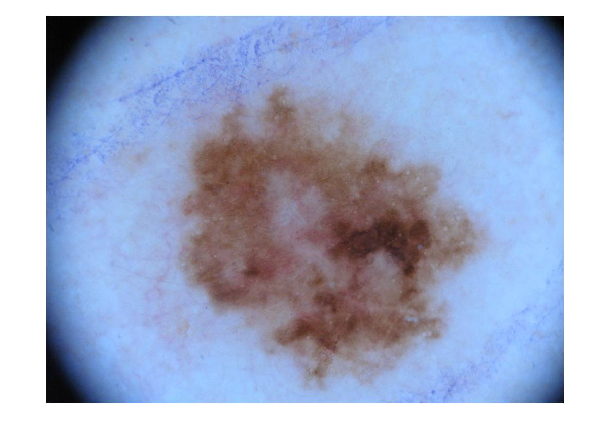

imshow(readimage(imds,1))

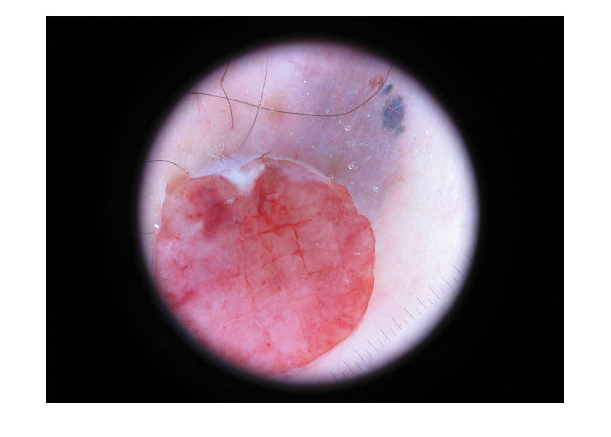

imshow(readimage(imds,2))

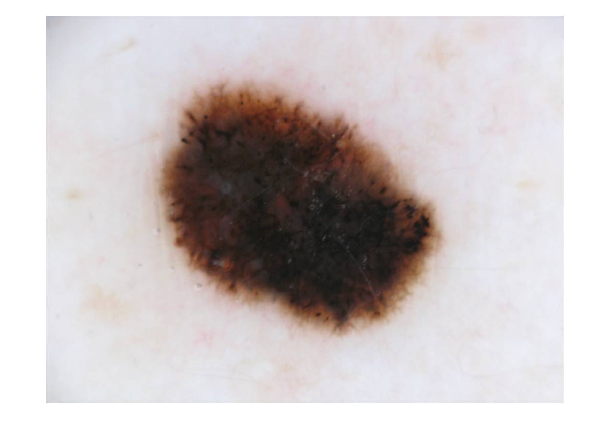

imshow(readimage(imds,3))

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,"randomized");

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([224 224],trainImgs,"ColorPreprocessing","gray2rgb");
testds = augmentedImageDatastore([224 224],testImgs,"ColorPreprocessing","gray2rgb");

## Build a network

Start with a pretrained network

net = googlenet;
lgraph = layerGraph(net);

Take the CNN layer graph and replace the output layers.

newFc = fullyConnectedLayer(2,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Set some training options

options = trainingOptions("sgdm","InitialLearnRate", 0.001);

## Train the network

wormsnet = trainNetwork(trainds,lgraph,options)

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       39.06% |       1.9432 |          0.0010 |
|       4 |          50 |       00:01:25 |       87.50% |       0.3406 |          0.0010 |
|       8 |         100 |       00:02:45 |       89.06% |       0.2604 |          0.0010 |
|      12 |         150 |       00:04:06 |       89.84% |       0.2381 |          0.0010 |
|      16 |         200 |       00:05:26 |       92.97% |       0.1907 |          0.0010 |
|      20 |         250 |       00:06:47 |       98.44% |       0.0755 |          0.0010 |
|      24 |         300 |  

wormsnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Evaluate network on test data

Make predictions

save("wormsnet.sav")
preds = classify(wormsnet,testds);

Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.8265

View confusion matrix

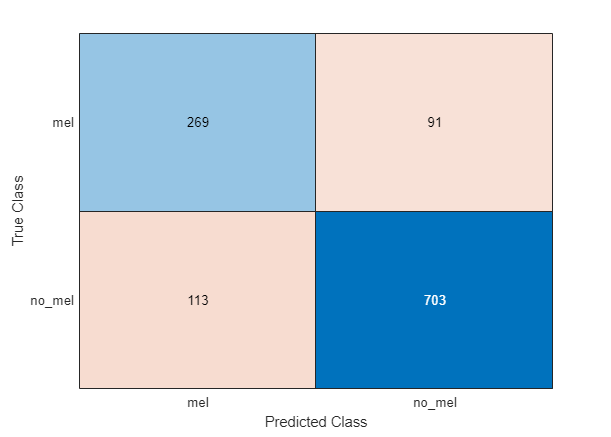

confusionchart(truetest,preds);

View first incorrect classification (if there is one)

idx = find(preds~=truetest)

idx =      2
    34
    40
    41
    42
    49
    52
    55
    63
    72


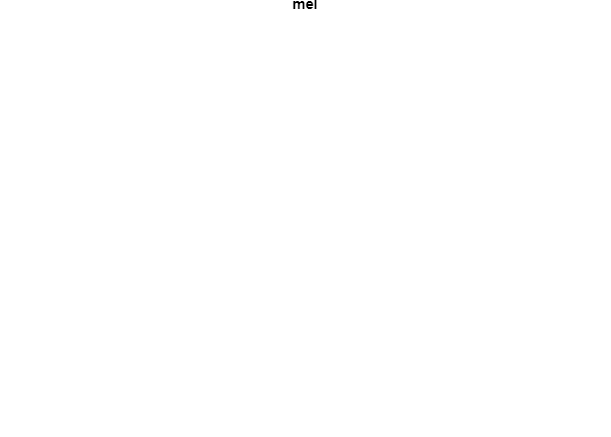

if ~isempty(idx)
    imshow(readimage(testImgs,idx(1)))
    title(truetest(idx(1)))
end

Generate Images From GAN

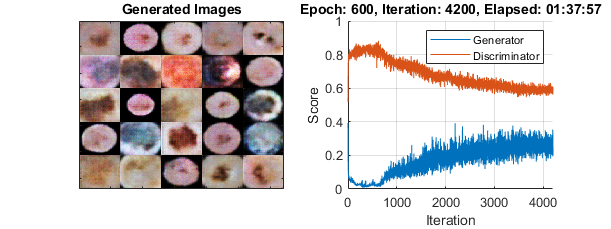

load("Save_GAN_4_128b_600e.mat")